# Solução do problema de fluxo de potência.

**Figura 1 **- Diagrama unifilar do circuito a ser analisado

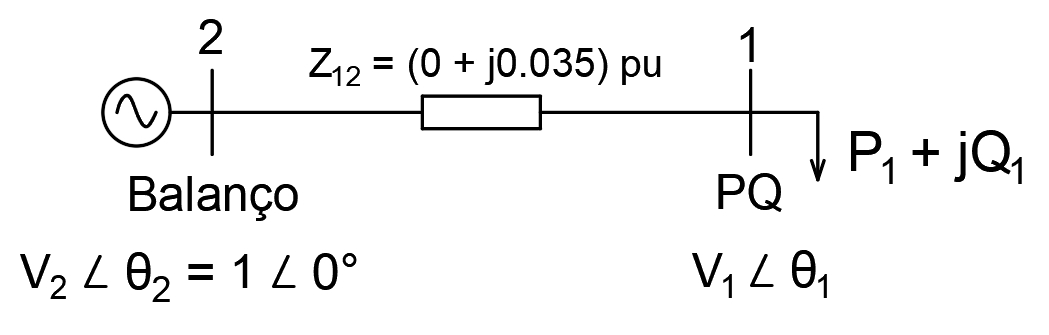

Fonte: Elaborada pelo autor

%   Apenas garantindo que a tela de comando inicie sem conteúdo prévio e que
% não haja nenhum dado guardado de programas anteriores.
clear 
clc


## Número de barramentos (entrada do usuário):

### ***Formato padrão da entrada:***

*    numBarra deverá ser igualado ao número de barramentos do sistema. *

*Exemplo: Um sistema com três barramentos.*

*numBarra = 3;*

numBarra = 2;

São criada as matrizes e variáveis que serão utilizadas ao longo do programa.

SLACK = 1;
PV = 2;
PQ = 3;
matriz_P = sym("P" , [numBarra , 1]);
matriz_Q = sym("Q" , [numBarra , 1]);
assume(matriz_Q, 'real');
matriz_theta = sym("theta" , [1 , numBarra]);
matriz_V = sym("V" , [1 , numBarra]);
matriz_YG = zeros(numBarra , 1);



## Especificações de impedância do sistema (entrada do usuário): 

### Impedância da linha de transmissão:

    Se faz indispensável definir o valor das impedâncias das LTs para que o programa funcione corretamente. Seus valores deverão ser especificados em p.u. (por unidade). Para defini-los, deve-se atribuir o valor dos elementos matriz_Z( p, q ) da matriz_Z, onde **p** é o barramento extremo de entrada da LT, e **q** é o barramento do extremo de saida. Caso não haja LT entre os barramentos p,q, deve-se definir seu valor de impedância como zero ( matriz_Z( p , q ) = 0 ).

    Como estamos resolvendo o problema 5.4 especificado, iremos preencher com os dados do mesmo:

**  Tabela 1** - Dados das linhas de transmissão.

Fonte: Elaborada pelo autor

### ***Formato padrão da entrada:***

*    Caso houver necessidade de adicionar ao sistema um n-ésimo barramento:*

*    matriz_Z( n ,  A ) = valor especificado;*

*    matriz_Z( A ,  n ) = valor especificado;*

*ou*

*    matriz_Z( n , B ) = 0;*

*    matriz_Z( N , n ) = 0;*

*   Onde A representa todos os barramentos em que existe LT entre n e A*

*e B representa todos os barramentos em que não existe LT entre n e B *

*Exemplo: Deseja-se adicionar ao problema em análise um 3*º barramento. Este tem conexão (LT) conectando-o **apenas** ao barramento 1. Esta LT tem como valor de impedância Z = (0.005 + j0.004) p.u

*Deverá ser adicionado ao código:*

matriz_Z(1 , 3) = 0.005 + j*0.004;

matriz_Z(3 , 1) = 0.005 + j*0.004;

matriz_Z(1 , 2) = 0;

matriz_Z(2 , 1) = 0;

% Input do usuário: especificações das Linhas de Transmissão (LTs):
matriz_Z = zeros(numBarra,numBarra);

% Impedância da LT entre os barramentos 1-2 ou 2-1 (em pu):
matriz_Z(1,2) = 0 + j*0.0350;
matriz_Z(2,1) = 0 + j*0.0350;




### Admitância entre o barramento e a terra:

    É possível que não seja especificado ou utilizado este valor no problema. Caso seja o caso deixe de preenche-lo. Abaixo apenas são atribuidos como zero para enfatizar a sua existência no problema.

    Como no caso em análise esta **não é especificada**, deixaremos como zero os valores respectivos.

### ***Formato padrão da entrada:***

*    Caso deseja-se adicionar no sistema um n-ésimo barramento:*

*    matriz_YG( n ) = valor especificado;*

*ou*

*    matriz_YG( n ) = 0;*

*Exemplo: Deseja-se adicionar ao problema em análise um 3*º barramento. Este tem valor de sua admitância barramento-terra $Y_G =\left(0\ldotp 0+\mathrm{j0}\ldotp 055\;\right)\;\mathrm{pu}$


% Admitância barramento-terra na barra 1, em pu:
matriz_YG(1) = 0 ;

% Admitância barramento-terra na barra 2, em pu:
matriz_YG(2) = 0 ;



### Matriz admitância:

    Após especificados todos parâmetros relacionando impedâncias no sistema, chama-se a função **matriz_admitancia() **, a qual faz o cálculo da matriz admitância do sistema em questão, em pu.

% Formando a matriz admitância:
matriz_Y = matriz_admitancia(matriz_Z, matriz_YG);


### Análise da matriz admitância (Y):

    Analisando a saida da função **matriz_admitância() **já é possível que seus dados estão de acordo com os constados no livro:

**Tabela 2 - **Matriz admitância calculada pelo programa em pu.

Fonte: Elaborada pelo autor

## Especificações dos dados dos barramentos **(entrada do usuário)**:

    Nesta seção deverão ser especificados os dados dos n barramentos ( no caso numBarra = 2 barramentos). Cada barramento pode ser um dos três tipos: barramento de **Referência** ou **Folga **(ou Slack em inglês), **PV** ou **PQ.** Cada tipo de barramento deve ser especificados valores diferentes:

- **SLACK: **Deverá ser especificado um valor para tensão (** matriz_V( p ) **) , onde p é o número do barramento em questão) e o valor do ângulo de fase deve ser zero ( **matriz_theta( p )** = 0 ).

- **PV: **Deverá ser especificado um valor para potência ativa P ( **matriz_P( p )** ) e para tensão (** matriz_V( p ) **).

- **PQ**: Deverá ser especificado um valor para potência ativa P ( **matriz_P( p )** ) e para potência reativa Q ( **matriz_Q( p )** ).

 Para tal, deve-se associar cada barramento ao seu tipo ( Tipo_barra(p) = {"SLACK" , "PV" ou "PQ"} ). O valor especificado deverá constar exatamente igual ao conteúdo entre aspas, sendo o correto **Tipo_barra(p) = "SLACK"**, e por exemplo, um uso incorreto Tipo_barra(p) = slack ou Tipo_barra(p) = Slack.

### ***Formato padrão da entrada:***

*    Caso houver necessidade de adicionar ao sistema um n-ésimo barramento:*

*    Se o barramento for do tipo balanço ( ou ****SLACK**** em inglês):*

*Tipo_barra( n ) = SLACK;*

*matriz_V( n ) = valor especificado em pu. ;*

*matriz_theta ( n ) = 0;*

*    Se o barramento for do tipo ****PV****:*

*Tipo_barra( n ) = PV;*

*matriz_P( n ) = valor especificado em pu ;*

*matriz_V( n ) = valor especificado em pu ;*

*    Se o barramento for do tipo ****PQ****:*

*Tipo_barra( n ) = PQ;*

*matriz_P( n ) = valor especificado em pu ;*

*matriz_Q( n ) = valor especificado em pu ;*

*Exemplo: Deseja-se adicionar ao problema em análise um 3*º barramento tipo PV, onde a potência injetada é P = 1 *pu* e a tensão

V = 1.06 *pu*

*Deverá ser adicionado ao código:*

Tipo_barra(3) = PV;

matriz_P(3) = 1.00;

matriz_V(3) = 1.06;


% Input do usuário: especificações dos barramentos:
% Se for barra tipo SLACK, deve-se definir o valor da tensão (1 pu) e ângulo (0 rad)
% Se for barra tipo PV, deve-se definir Potência ativa injetada em pu e magnitude da tensão em pu.
% Se for barra tipo PQ, deve-se definir Potência ativa injetada em pu e Potência reativa injetada em pu.


% Barramento 1: PQ
Tipo_barra(1) = PQ;
matriz_P(1) = -1.0;
matriz_Q(1) = -0;
    


% Barramento 2: SLACK
Tipo_barra(2) = SLACK;
matriz_V(2) = 1.00;
matriz_theta(2) = 0;



### Potência especificada:

    Forma um vetor coluna contendo os valores previamente especificados de potência ativa e reativa, assim como os valores não especificados, em forma de variáveis livres:

**Figura 2 - **Valor da potência total.

Fonte: ELECTRIC POWER SYSTEM: A FIRST COURSE, 2012, página 82

P_esp = vpa(matriz_P + j * matriz_Q);


No exemplo em questão, P_esp teria contido em suas linhas:

**Figura 3 - ** Valor contido no vetor P_esp, em pu.

Fonte: Elaborada pelo autor.

## Obtendo vetor coluna conténdo variáveis e chutes para o método Newthon-Raphson:

    Conforme necessário no método Newthon-Raphson, um vetor com valores iniciais para as variáveis livres das funções se faz necessário. Além disso, é necessário conhecer quais são as variáveis livres em si para o cálculo das derivadas parciais (Jacobiano). Então é chamada a função **obter_dadosNR() **que realiza ambas as tarefas descritas acima.


% Construindo o vetor chute X0 e as variáveis para o método NR:
[X0 , variaveis_NR] = obter_dadosNR(Tipo_barra);

A saida da função **obter_dadosNR() **é um vetor coluna chute X0 e um vetor linha contendo todas variáveis livres do sistema.

**Figura 3** - Valores contidos nos vetores X0 e variaveis_NR. 

Fonte: Elaborada pelo autor.

    Vale salientar que os elementos de **X0** ,apesar de ser um vetor coluna, são respectivamente equivalentes ao chute inicial das variáveis contidas no vetor linha **variaveis_NR** , onde os valores inicias são: theta2 = 0 , theta3 = 0 e V3 = 0.


% Contando número de barramentos PV e PQ:
[nPV , nPQ] = contBarramentos(Tipo_barra);


## Equações básicas de fluxo de potência:

    Conforme deduzido no livro, será utilizada as fórmulas para equações básicas de fluxo de potência:

**Figura 4** - Equações de potência fornecidas por cada barramento.

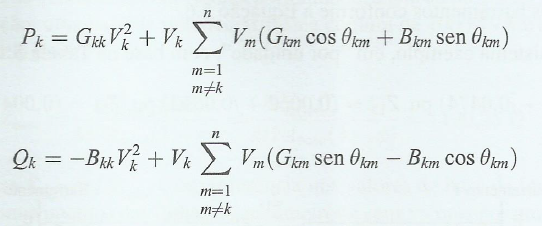

Fonte: ELECTRIC POWER SYSTEM: A FIRST COURSE, 2012, página 82.

Obtém-se da função **func_potencia() **dois vetores colunas: **equacao_potencia_NR, **que contém as funções em forma de texto (string) das potências deconhecidas (descrita acima) e **f_potencia_geral **que contém as potências conhecidas ( especificadas anteriormente ) e as desconhecidas ( descritas acima).

% Obtendo as equações de potência:
[equacao_potencia_NR , f_potencia_geral] = func_potencia(nPV , nPQ , P_esp, Tipo_barra ,matriz_V , matriz_theta, matriz_Y);


### Função de potência geral:

    Constroi-se a função numérica **P_numeric_geral** propriamente dita a partir do vetor **f_potencia_geral** contendo as funções em forma de texto.


sym_P_geral = symfun(f_potencia_geral , variaveis_NR);
P_numeric_geral = matlabFunction(sym_P_geral);


## Método Newton-Raphson:

    Em posse das previamente calculadas equações básicas de potência em forma de texto ( **equacao_potencia_NR **) , variáveis livres do sistema ( **variaveis_NR **) e chute das variáveis livres ( **X0** ) poderá ser calculada as raízes das equações de potência. Além disso, deverá ser especificado uma tolerância para as raízes obtidas e um número limite de iterações.

maximo_de_iteracoes = 1000;
tolerancia = 1.0e-20;
[final_X , final_JAC , iteracoes] = NewtonRaphson(equacao_potencia_NR , variaveis_NR , X0, maximo_de_iteracoes, tolerancia);


### Saída do método Newton-Raphson:

    Depois de ser realizado o método Newthon-Raphson por meio da função de mesmo nome: **NewtonRaphson() **é retornado dela três parâmetros:

- **final_X**: vetor coluna contendo as raizes aproximadas das equações de potência.

- **final_JAC**: o valor numérico do jacobiano da última iteração

- **iteracoes**: número de iterações necessárias para alcançar os valores descritos acima.

### Impressão dos dados de potência, ângulo da fase e tensão  por barramento:

    Chamando funções personalizadas **printP_barras()** , **printX()**  são impressos os dados ,previamente calculados, na tela de comandos do usuário.

fprintf("Número de iterações = %d ", iteracoes);

Número de iterações = 6 

cell_X = num2cell(final_X);
P_das_barras = P_numeric_geral(cell_X{:});
printP_barras(P_das_barras);



Potência fornecida por cada barramento. 
 n |     P + Q*i [pu]
------------------------------
 1 |   -1.00000+0.000000i 
 2 |    1.00000+0.035043i 



printX(variaveis_NR , final_X, matriz_V, matriz_theta);



Tensão e ângulo nos barramentos.
 n |     V  [pu]  |  θ [rad]
------------------------------
 1 |    0.99939   |   -0.03503 
 2 |    1.00000   |    0.00000 


### Cálculo do fluxo de potência nas LTs:

    Em posse dos dados das raízes das equações de potência, calcula-se os valores de fluxo de potência das LTs usando a seguinte fórmula como base:

####   
$$S_{pq} =\ P_{pq} \ +\ jQ_{pq}$$


#### 
$$P_{pq} \ +\ jQ_{pq} =\bar{V_p } {\;\bar{I} }^* \;,\left(I=\frac{V_q -V_j }{Z_{\mathrm{pq}} }\right)$$


Portando utilizaremos para o cálculo de fluxo de potência nas LTs:

### 
$$P_{\mathrm{pq}} +j{\mathrm{Q}}_{\mathrm{pq}} =V_p \;\left(\frac{{V_q }^* -{V_j }^* }{{Z_{\mathrm{pq}} }^* }\right)\;$$


[P_nas_LTs] = flxuo_potencia_LT(variaveis_NR , final_X , matriz_V, matriz_theta, matriz_Z);
printP_LTs(P_nas_LTs);



Fluxo de potência ativa e reativa entre os barramentos p e q.
  p -> q |    P + Q * i [pu]   
---------------------------------
  1 -  2 |   -1.00082+0.017541i 
  2 -  1 |    1.00082+0.017527i 


## REFERÊNCIAS BIBLIOGRÁFICAS:

[1] POWER flow in power system networks. *In*: MOHAN, Ned. **Electric Power System**: A first course. 1. ed. Denver: John Wiley & Sons, Inc., 2012. v. 1, cap. 5, p. 78-93. ISBN 978-1-118-07479-4.

[2]  LOAD flow studies. *In*: STAGG, Glenn W.; EL-ABIAD, Ahmed H. **Computer methods in power system analysis**. International Student edition. ed. [*S. l.*]: McGraw-Hill Inc., 1968. v. 1, cap. 8, p. 257-333. ISBN 978-0070857643.